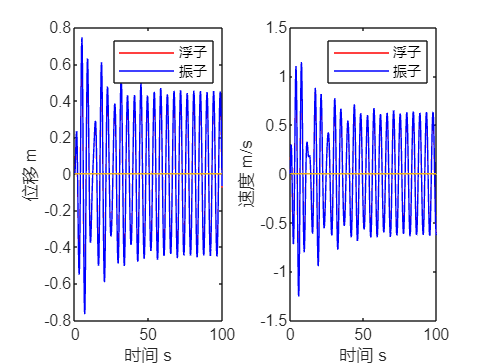

w = 1.4005; %入射波浪频率
T = (2*pi)/w*40; %前40个波浪周期 
h = 1e-4; %步进长度
t = 0:h:T; %生成自变量t的向量  一个数组，从0开始，0.0001为间距，直到T

m_fz = 4866; %浮子的质量
m_z = 2433; %振子的质量
m_fu = 1335.535; %垂荡附加质量
S = m_fz + m_fu; %受力分析考虑的总质量
c_x = 656.3616; %垂荡兴波阻尼系数
rho = 1025; %海水密度
g = 9.8; %重力加速度
A = pi; %圆柱底面积
zf = 6250; %垂荡激励力振幅 就是f
K_t = 80000; %弹簧刚度
B = rho*g*A;
V = (0.8*A)/3; %圆锥体积

%问题一第一种情况  直线阻尼器的阻尼系数
K_zn = 10000;

%创建计算结果xyzm的数组
N = length(t);
x = zeros(1,N);
y = zeros(1,N);
z = zeros(1,N);
m = zeros(1,N);

%四阶龙格库塔迭代
for i = 2:N
    t_n = t(i-1);
    x_n = x(i-1); %浮子的位移
    y_n = y(i-1); %振子的位移
    z_n = z(i-1); %z_n = u(t)
    m_n = m(i-1); %m_n = w(t)

    %写一阶微分方程
    kx1 = z_n; 
    ky1 = m_n; 
    kz1 = (zf*cos(w*t_n) + K_zn*(m_n - z_n) + K_t*(y_n - x_n) - c_x*z_n - B*x_n) / S; %u'(t)
    km1 = -(K_zn*(m_n - z_n) + K_t*(y_n - x_n)) / m_z;

    kx2 = z_n + kz1*h/2;
    ky2 = m_n + km1*h/2;
    kz2 = (zf*cos(w*(t_n + h/2)) + K_zn*(m_n + km1*h/2 - z_n - kz1*h/2) + K_t*(y_n + ky1*h/2 - x_n - kx1*h/2) - c_x*(z_n + kz1*h/2) - B*(x_n + kx1*h/2)) / S; 
    km2 = -(K_zn*(m_n + km1*h/2 - z_n - kz1*h/2) + K_t*(y_n + ky1*h/2 - x_n - kx1*h/2)) / m_z;

    kx3 = z_n + kz2*h/2;
    ky3 = m_n + km2*h/2;
    kz3 = (zf*cos(w*(t_n + h/2)) + K_zn*(m_n + km2*h/2 - z_n - kz2*h/2) + K_t*(y_n + ky2*h/2 - x_n - kx2*h/2) - c_x*(z_n + kz2*h/2) - B*(x_n + kx2*h/2)) / S; 
    km3 = -(K_zn*(m_n + km2*h/2 - z_n - kz2*h/2) + K_t*(y_n + ky2*h/2 - x_n - kx2*h/2)) / m_z;

    kx4 = z_n + kz3*h;
    ky4 = m_n + km3*h;
    kz4 = (zf*cos(w*(t_n + h)) + K_zn*(m_n + km3*h - z_n - kz3*h) + K_t*(y_n + ky3*h - x_n - kx3*h) - c_x*(z_n + kz3*h) - B*(x_n + kx3*h)) / S; 
    km4 = -(K_zn*(m_n + km3*h - z_n - kz3*h) + K_t*(y_n + ky3*h - x_n - kx3*h)) / m_z;

    x(i) = x_n + h/6*(kx1 + 2*kx2 + 2*kx3 + kx4);
    y(i) = y_n + h/6*(ky1 + 2*ky2 + 2*ky3 + ky4);
    z(i) = z_n + h/6*(kz1 + 2*kz2 + 2*kz3 + kz4);
    m(i) = m_n + h/6*(km1 + 2*km2 + 2*km3 + km4);
end

%画图,这是绝对位移
figure();
subplot('121');
plot(t,x,'r');
hold on

plot(t,y,'b');
plot([0,T],[0,0]);
legend('浮子','振子');
xlabel('时间 s');
ylabel('位移 m');
xlim([0, 100]);

subplot('122');
plot(t,z,'r');
hold on

plot(t,m,'b');
plot([0,T],[0,0]);
legend('浮子','振子');
xlabel('时间 s');
ylabel('速度 m/s');
xlim([0, 100]);

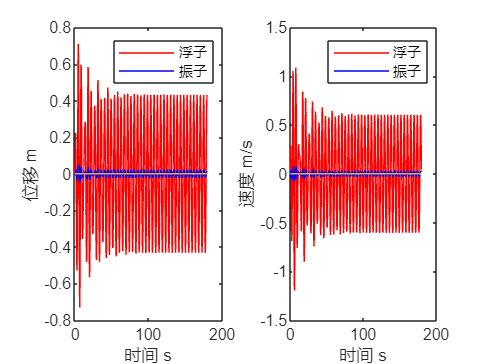


%这是相对位移

figure();
subplot('121');
plot(t,x,'r');
hold on

plot(t,y-x,'b');
plot([0,T],[0,0]);
legend('浮子','振子');
xlabel('时间 s');
ylabel('位移 m');

subplot('122');
plot(t,z,'r');
hold on

plot(t,m-z,'b');
plot([0,T],[0,0]);
legend('浮子','振子');
xlabel('时间 s');
ylabel('速度 m/s');



resfx=[];
resfv=[];
reszx=[];
reszv=[];
cout = 0;

%遍历时间间隔为0.2s，前40个波浪周期的垂荡位移和速度
start = find(t==0);
over = find(t==0.2);
dtt = over - start;
index = 1;
for xx = 0:0.2:T
    cout = cout + 1;
    %查找对应时间所在的位置
    %记录位移速度
    resfx(cout) = x(index);%浮子位移
    rexzx(cout) = y(index);%振子位移
    resfv(cout) = z(index);%浮子速度
    reszv(cout) = m(index);%振子速度
    index = index + dtt;
end

time = 0:0.2:T;
result = [time',resfx',resfv',reszx',reszv'];
xlswrite('myresult1',result)


